T = readtable("nlfit.csv")

T = 21×2 table
    V       A   
    __    ______

     0         0
     1    0.0488
     2    0.0702
     3    0.0819
     4     0.096
     5     0.107
     6    0.1094
     7    0.1245
     9    0.1279
    11    0.1576
    14    0.1548
    16    0.1744
    20    0.1856
    25    0.2098
    30    0.2662
    37    0.2885


v = T{1:end,"V"}

v =      0
     1
     2
     3
     4
     5
     6
     7
     9
    11


a = T{1:end,"A"}

a =          0
    0.0488
    0.0702
    0.0819
    0.0960
    0.1070
    0.1094
    0.1245
    0.1279
    0.1576


pf = polyfit(v,a,1)

pf =     0.0041    0.0869


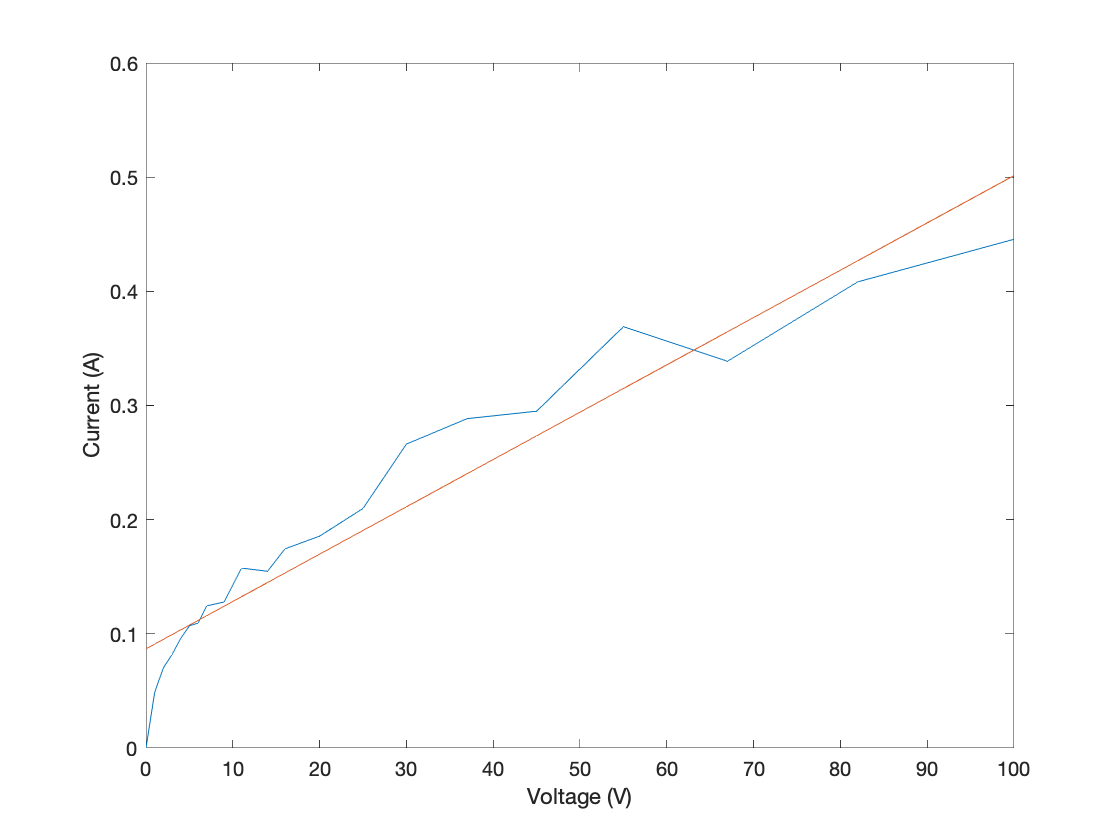


plot(v, a, v, polyval(pf,v))
xlabel('Voltage (V)')
ylabel('Current (A)')